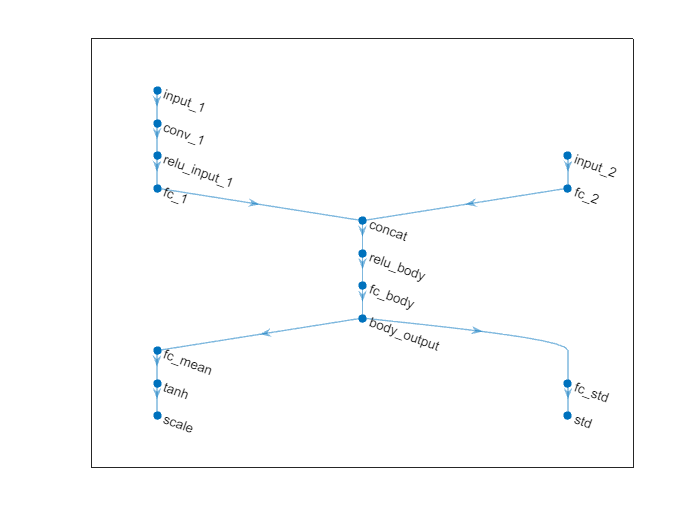

%从预定义好的环境中直接创建
env = rlPredefinedEnv("SimplePendulumWithImage-Continuous");
obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);
rng(0);

initOpts = rlAgentInitializationOptions("NumHiddenUnit", 128,"UseRNN", false);
agentoption = rlACAgentOptions(DiscountFactor=0.95,SampleTime = -1);

agent = rlACAgent(obsInfo,actInfo,initOpts,agentoption);

actorNet = getModel(getActor(agent));
criticNet = getModel(getCritic(agent));
plot(layerGraph(actorNet));

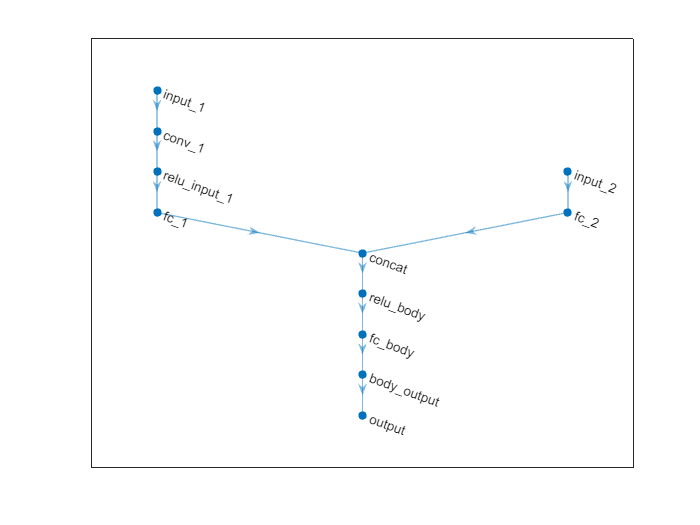

plot(layerGraph(criticNet));

trainOpts = rlTrainingOptions( ...
    MaxEpisodes=2000 ,...
    MaxStepsPerEpisode=3000,...
    StopTrainingCriteria='EpisodeReward',...
    StopTrainingValue = 40,...
    SaveAgentCriteria='EpisodeReward',...
    SaveAgentValue = 40,...
    Verbose=true,...
    Plots='none') ; 

plot(env) 
trainingStats = train(agent ,env,trainOpts);

Episode:   1/2000 | Episode reward: -15277.70 | Episode steps: 3000 | Average reward: -15277.71 | Step Count: 3000 | Episode Q0:   -42.90
Episode:   2/2000 | Episode reward: -19132.59 | Episode steps: 3000 | Average reward: -17205.15 | Step Count: 6000 | Episode Q0:   -83.06
Episode:   3/2000 | Episode reward: -23185.05 | Episode steps: 3000 | Average reward: -19198.45 | Step Count: 9000 | Episode Q0:  -140.76
Episode:   4/2000 | Episode reward: -20250.94 | Episode steps: 3000 | Average reward: -19461.57 | Step Count: 12000 | Episode Q0:   -41.61
Episode:   5/2000 | Episode reward: -25847.30 | Episode steps: 3000 | Average reward: -20738.71 | Step Count: 15000 | Episode Q0:  -171.73
Episode:   6/2000 | Episode reward: -25889.78 | Episode steps: 3000 | Average reward: -22861.13 | Step Count: 18000 | Episode Q0:  -172.76
Episode:   7/2000 | Episode reward: -25889.78 | Episode steps: 3000 | Average reward: -24212.57 | Step Count: 21000 | Episode Q0:  -172.75
Episode:   8/2000 | Episode re